Exercici 1:

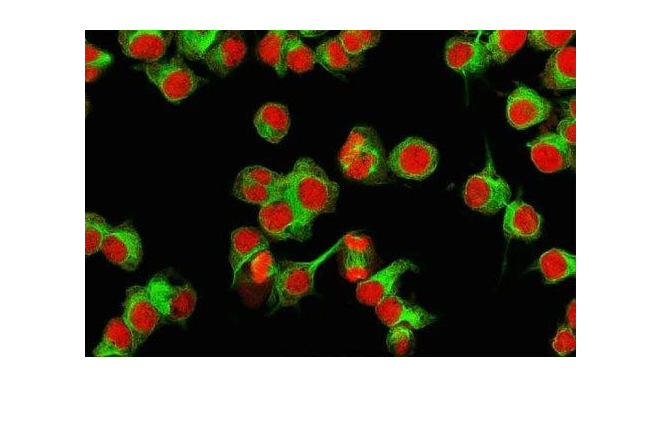

I = imread('flourescent_cell_780x520.jpg');
imshow(I);

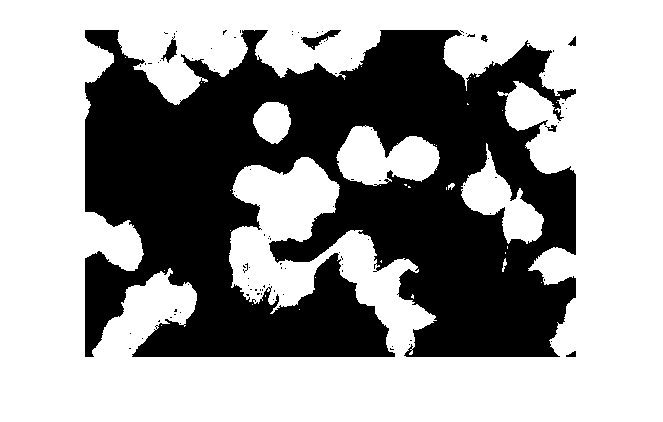

ndg = rgb2gray(I);
FG = ndg > 20;
imshow(FG);

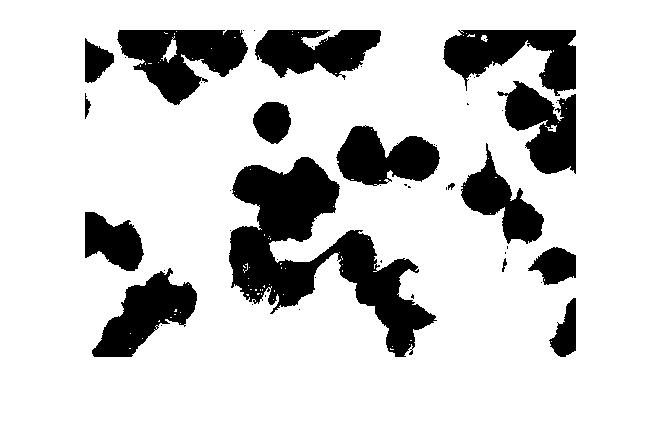

BG = not(FG);
imshow(BG, []);

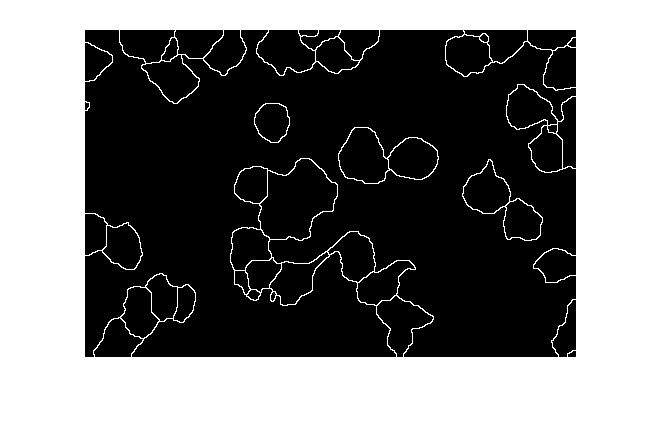

TD = bwdist(BG, 'euclidean');
TD = -TD;
TD(BG) = -Inf;
TDF = medfilt2(medfilt2(medfilt2(medfilt2(medfilt2(TD)))));
WS = watershed(TDF);
RGB = (WS == 0);
RGB = im2uint8(RGB);
imshow(RGB);

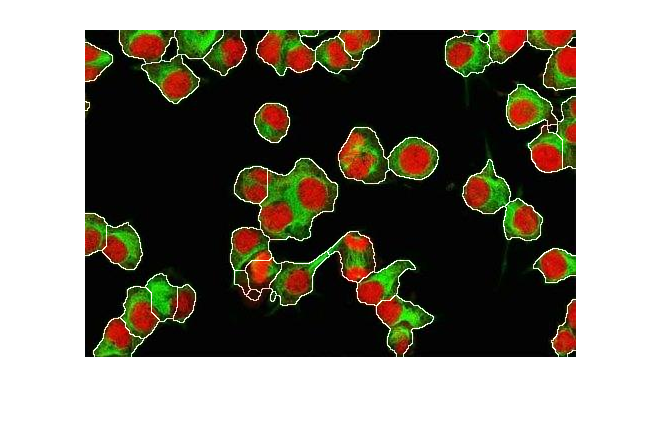

Res = I + RGB;
imshow(Res);